# Rad229_Eddy_Currents_Demo.mlx

## Background 

This script demonstrates the convolution of a single (or multiple) time-constant eddy current impulse response function (EC-IRF), e(t), with a monopolar (or bi-polar) trapezoidal gradient waveform. Recall, 


$$e(t)=H(t)\sum_n\alpha_n e^{-\frac{t}{\tau_n}}$$


Each EC-IRF has an amplitude $\alpha_n$ [$s$] and time constant $\tau_n$ [s]. Herein, we consider the effect of the eddy current response on the gradient field that is generated. The eddy currents can effect any gradient axis and, in fact, the $G_x$ gradient can induce an eddy current on the $G_y$ or $G_z$ axes, which we call "cross terms". Herein, we will examine the eddy current gradient ($G_{eddy}$) that is generated along the x-axis by the application of a $G_x$ gradient, which we term $G_{eddy,xx}$. This arises from time-varying active gradients that induce currents in nearby conducting structures (e.g. cryostat). These induced currents create magnetic fields that oppose (Lenz's Law) the target magnetic field. They are generated during active gradient slewing and decay during periods of gradient inactivity. 


$$G_{eddy,xx}(t)=\left( -\frac{dG_x(t)}{dt} \ast \sum_n \alpha_{xx,n} e^{-\frac{t}{\tau_{xx,n}}} \right)\hat{k}$$


We are examing the impact of eddy currents on the gradient waveform because it is a little easuer to visualize. Eddy currents also modulate the $B_0$ field and cause and, in general, $B_{0,eddy}$ is different for each gradient axis. You can read more about this in the "***Handbook of MRI Pulse Sequences***" by Matt Bernstein and colleagues. See Chapter 10.3.

Code Creation: Matt Middione

DBE@STANFORD.EDU (April 2021) for Rad229

## Eddy Current Demo Questions:

1) What do you observe about the magnitude of B0,e right after MONOPOLAR gradient activity for really short time constants? Intermediate time constants? Long time constants? Based on your observations which time constants are most problematic? 

2) Reconsider Problem #1, but for bipolar gradient waveforms.

3) Simulate the effect of multiple eddy current time constants? How do you pick each alpha?

4) [Advanced] The impact of eddy currents on gradient waveform fidelity can be small (even negligible) even for large gradients. For example, eddy currents have a relatively small effect on the b-value of the diffusion encoding gradients. However, the eddy currents generated by diffusion encoding gradients persist beyond the interval of diffusion encoding. Can you explain what artifacts can they can cause?   

5) [Advanced] Make a 2D surface plot of B0,e at the end of a monopolar gradient waveform for a range of Gx.G_rise and Gx.G_flat durations. Compare this to a similar plot for the bipolar gradient waveforms.

## Define the gradient waveform

%% Define MRI system constants
sys = Rad229_MRI_sys_config;
Gx.dG = sys.S_max * sys.dt;   % Maximum gradient increment per time step [T*s/m]

%% Build Mono-SLEW Gradient (We can't really do this...)
% Gx.G_rise = 0 : Gx.dG : sys.G_max;                 % Gradient ramp-up [T/m]
% Gx.G_flat = sys.G_max * ones(1,50);                % Gradient flat top [T/m]
% Gx.G = [Gx.G_rise Gx.G_flat];                      % Concatenate the gradient events
% Gx.t = 0 : sys.dt : sys.dt * ( length(Gx.G) - 1 ); % Time vector [s]

%% Build Monopolar Gradient
Gx.G_rise = 0 : Gx.dG : sys.G_max;                 % Gradient ramp-up [T/m]
Gx.G_flat = sys.G_max * ones(1,50);                % Gradient flat top [T/m]
Gx.G_fall = sys.G_max : -Gx.dG : 0;                % Gradient ramp-down [T/m]
Gx.G = [Gx.G_rise Gx.G_flat Gx.G_fall];            % Concatenate the gradient events
Gx.t = 0 : sys.dt : sys.dt * ( length(Gx.G) - 1 ); % Time vector [s]

%% Bipolar Gradient
% Gx.G = [Gx.G_rise Gx.G_flat Gx.G_fall -Gx.G_rise(2:end) -Gx.G_flat -Gx.G_fall];  % Concatenate the gradient events [T/m]
% Gx.t =  0 : sys.dt : sys.dt * ( length(Gx.G) - 1 );  % Time vector [ms]

Gx.SR = [ diff(Gx.G) 0 ] ./ sys.dt;                  % Slewrate calculation [T/m/s]

## Plot the gradient and slewrate waveforms

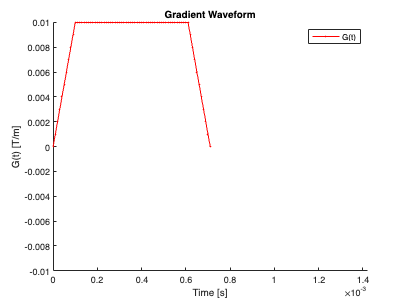

figure; hold on;
  title( 'Gradient Waveform' )  
  xlabel( 'Time [s]' ); ylabel( 'G(t) [T/m]' );
    plot( Gx.t , Gx.G , 'r.-' );  legend( 'G(t)' ); axis([0 2*max(Gx.t) -sys.G_max sys.G_max]);

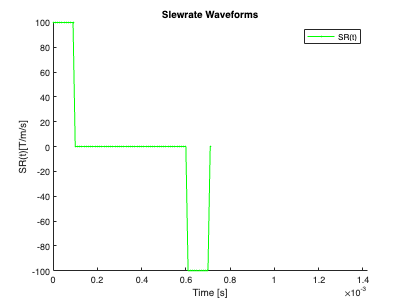


figure; hold on;
  title( 'Slewrate Waveforms' )  
  xlabel( 'Time [s]' ); ylabel( 'SR(t)[T/m/s]' );
    plot( Gx.t , Gx.SR , 'g.-' ); legend( 'SR(t)' ); axis([0 2*max(Gx.t) -sys.S_max sys.S_max]);

## Define the eddy current impulse response function:


$$e(t)=H(t)\sum_n\alpha_n e^{-\frac{t}{\tau_n}}$$


sys.tau(1) = 10.0e-3;                          % Eddy current time constant [s]
sys.alpha(1) = 0.1e-6;                         % Eddy current amplitude [µT*m/T]
t_eddy = 0 : sys.dt : 10 * ( max(sys.tau) );   % Time vector [ms]

% Add a second eddy current time constant
% sys.tau(2) = 5.0e-3;           % Eddy current time constant [s]
% sys.alpha(2) = 5.0e-6;         % Eddy current amplitude [µT*m/T]

% Sum up the different monoexponential responses
e = zeros( 1 , length(t_eddy) );
for n = 1 : length(sys.tau)
  e = e + sys.alpha(n) * exp( -t_eddy / sys.tau(n) );
end

## Plot the Eddy Current Impulse Response

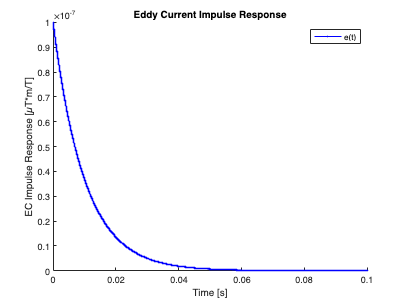

figure; hold on;
  title('Eddy Current Impulse Response')
  xlabel('Time [s]'); ylabel('EC Impulse Response [µT*m/T]');
  plot(t_eddy, e , 'b.-'); legend( 'e(t)' ); xlim([0 max(t_eddy)]);

## Define the resultant $B_0$ eddy current field


$$ \vec{B}_{0,eddy}(t)=\left( -\frac{d\vec{G}(t)}{dt} \ast \sum_n \alpha_n e^{-\frac{t}{\tau_n}} \right)\hat{k}$$


B0_e = conv( -Gx.SR , e );  % Zeroth order eddy current [µT]
t_e = 0 : sys.dt : sys.dt * ( length( B0_e ) - 1 );  % Time vector [s]

## Plot the resultant $B_0$ eddy current field

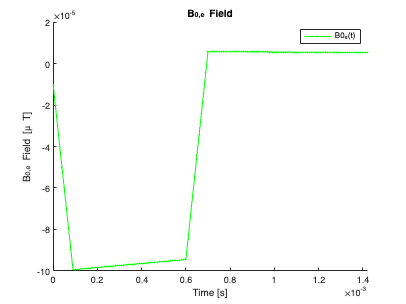

f=figure; hold on;
  title('B_{0,e} Field')  
  xlabel('Time [s]'); ylabel('B_{0,e} Field [\mu T]');
  plot(t_e , B0_e , 'g.-'); legend('B0_e(t)'); xlim([0 2*max(Gx.t)]);

We observe that this eddy current can impart a $B_0$ field shift of a up to -100 $\mu T$ during the application of the gradient, which accords with ~4257Hz in frequency. Note that the "plateau" value after the gradient is non-zero for some time. Note too that he $\alpha$ was picked somewhat arbitrarily.

## Define the resultant eddy current gradient $G_{eddy,xx}$

For now just assume the same eddy current impulse response function is acceptable. In general, there is no reason they should be the same. Note the resultant units are different so the appropriate $\alpha$ coefficient carries different units too.

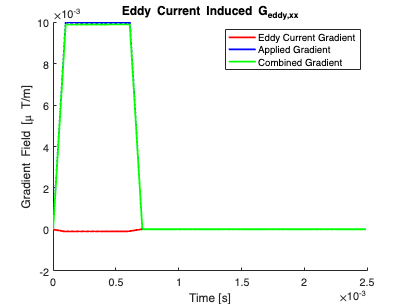

Gxx_e = conv( -Gx.SR , e ); % Eddy current induced gradient [µT/m]
ind_max = 250;
Gx.G = [ Gx.G zeros(1,ind_max-length(Gx.G)) ];

Gx_final = [ Gx.G + Gxx_e(1:ind_max) ];

figure; hold on;
  title('Eddy Current Induced G_{eddy,xx}')  
  xlabel('Time [s]'); ylabel('Gradient Field [\mu T/m]');
  p(1) = plot( t_e(1:ind_max) , Gxx_e(1:ind_max) ,'r');
  p(2) = plot( t_e(1:ind_max) , Gx.G ,'b');
  p(3) = plot( t_e(1:ind_max) , Gx_final ,'g');
  legend('Eddy Current Gradient','Applied Gradient','Combined Gradient');
  set(p , 'LineWidth' , 2); set(gca,'FontSize',12);

What you observe is that you don't quite get the gradient that you target be design because the eddy current induced gradient field always apposes the applied field according to Lenz's Law. **What are the consequences? What can you do about it?**

## Plot the resultant B0 eddy current field AND gradient field

% acq.Nx = 3; % Define the number of points to consider [#]
% acq.FOVx = 100e-3; % Define a small FOV to see the effect [m]
% acq.x_pos = linspace(-acq.FOVx/2 , acq.FOVx/2 , acq.Nx); % Define the pixel locations [m]
% 
% % Compute the B-field from the gradient at a few spatial positions
% for n = 1 : acq.Nx
%   B_grad( n , : ) = [ Gx.G zeros( 1 , length(B0_e) - length(Gx.G) ) ] .* acq.x_pos(n); % [T]
% end
% B_total = repmat( B0_e , [acq.Nx 1]) + B_grad; % Add the B0 eddy current field and the gradient fields [T]
% 
% f=figure; hold on;
%   title('Combined B_{0,e} Field + Gradient Field')  
%   xlabel('Time [s]'); ylabel('B-Field [\mu T]');
%   plot(t_e, B_total); xlim([0 2*max(Gx.t)]);  
%   plot( t_e , B_grad , 'k--' );
%   legend('-FOV/2 Combo' , 'Isocenter Combo' , '+FOV/2 Combo' , '-FOV/2 Grad' , 'Isocenter Grad' , '+FOV/2 Grad');

## What if you pre-emphasize the gradient waveform?

If we know the gradients are impacted by eddy currents can we "**pre-emphasize**" the gradient waveform (**Gx.G**) so that **Gx.G - Gxx_e** produces the targeted gradient? The idea is that we can change the shape of the input **Gx.G** so that the output **Gx.G** matches the design goal.

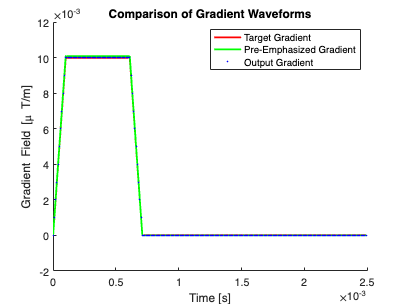

Gx_pre_emph = [ Gx.G - Gxx_e(1:ind_max) ];            % Define a pre-emphasized gradient waveform
Sx_pre_emph = [ diff(Gx_pre_emph , 1 , 2) 0 ];        % Slewrate calculation [T/m/s]

Gxx_e_pre = conv( -Sx_pre_emph , e  );                % Estimate the eddy current induced gradient
Gxx_e_pre = Gxx_e_pre( 1 : length(Gx_pre_emph) );

Gx_output = [ Gx.G + Gxx_e_pre(1:length(Gx.G)) ];

figure; hold on;
  title('Comparison of Gradient Waveforms')  
  xlabel('Time [s]'); ylabel('Gradient Field [\mu T/m]');
  p(1) = plot( t_e(1:length(Gx.G)) ,Gx.G , 'r');                % "Target" waveform
  p(2) = plot( t_e(1:length(Gx_pre_emph)) , Gx_pre_emph ,'g');  % Input "pre-emphasized" waveform
  p(3) = plot( t_e(1:length(Gx_output)) , Gx_output ,'b.');      % The final/output waveform
  legend('Target Gradient','Pre-Emphasized Gradient','Output Gradient');
  set(p , 'LineWidth' , 2); set(gca,'FontSize',12);

%   plot( t_e(1:length(Gxx_e_pre)) , Gxx_e_pre ,'b');      % 

% % G_pre = -B0_e + [ G zeros( 1 , length(B0_e) - length(G) ) ];  % Add the *opposite* of B0_e
% % S_pre = [ diff(G_pre) 0 ];                            % Slewrate calculation
% 
% G_pre = -repmat( B0_e , [acq.Nx 1]) + B_grad;  % Add B0_e + B_grad [T]
% S_pre = [ diff(G_pre , 1 , 2) ];               % Slewrate calculation [T/m/s]

% B_pre = repmat( -B0_e , [acq.Nx 1]) + B_grad; % Add the B0 eddy current field and the gradient fields [T]
% S_pre = [ diff(B0_e , 1 , 2) ];               % Slewrate calculation [T/m/s]

% acq.Nx = 3; % Define the number of points to consider [#]
% acq.FOVx = 100e-3; % Define a small FOV to see the effect [m]
% acq.x_pos = linspace(-acq.FOVx/2 , acq.FOVx/2 , acq.Nx); % Define the pixel locations [m]
% 
% for n = 1 : acq.Nx
%   G_grad( n , : ) = [ Gx.G zeros( 1 , length(B0_e) - length(Gx.G) ) ]; % [T/m]
% end
% S_pre = [ diff(B_grad , 1 , 2) zeros(acq.Nx,1) ];               % Slewrate calculation [T/m/s]
% 
% for n = 1 : acq.Nx
%   B0_pre = conv( -S_pre(n,:) , e  );                            % Zeroth order eddy current
%   G_post(n,:) = B0_pre + [G_grad(n,:) zeros( 1 , length(B0_pre) - length(G_grad) ) ];
% end
% 
% f=figure; hold on;
%   title('Pre-Emphasized Gradient Waveform Fields')  
%   xlabel('Time [s]'); ylabel('B-Field [\mu T]');
%   plot(t_e, B_total); xlim([0 2*max(Gx.t)]);  
%   plot( t_e , B_grad , 'k--' );
%   legend('-FOV/2 Combo' , 'Isocenter Combo' , '+FOV/2 Combo' , '-FOV/2 Grad' , 'Isocenter Grad' , '+FOV/2 Grad');
%   
% % G_post = B0_pre + [G_pre zeros( 1 , length(B0_pre) - length(G_pre) ) ];
% t_post = 0 : sys.dt : sys.dt * ( length( G_post ) - 1 );  % Time vector [ms]
% 
% f=figure; hold on; %set(gca,'FontSize',18)
%   r1=plot(t_e,G_grad,'r.-');
% %   r2=plot(t_e,S_pre,'g.-');
%   r3=plot(t_post,G_post,'b.-');
%   legend('G_{pre}(t)','B0_e(t)','G_{post}(t)');